clear all;
ros_ip = "192.168.212.128";
init(ros_ip)

Shutting down global node /matlab_global_node_22740 with NodeURI http://192.168.212.1:35961/ and MasterURI http://192.168.212.128:11311.
Initializing global node /matlab_global_node_50272 with NodeURI http://192.168.212.1:45117/ and MasterURI http://192.168.212.128:11311.


## here

% build the neural network
net = build_network;

  YOLOv2Net with properties:

         Name: 'robocup'
       Anchor: []
    DataStore: [1×1 matlab.io.datastore.CombinedDatastore]
     Detector: []
       LGraph: []



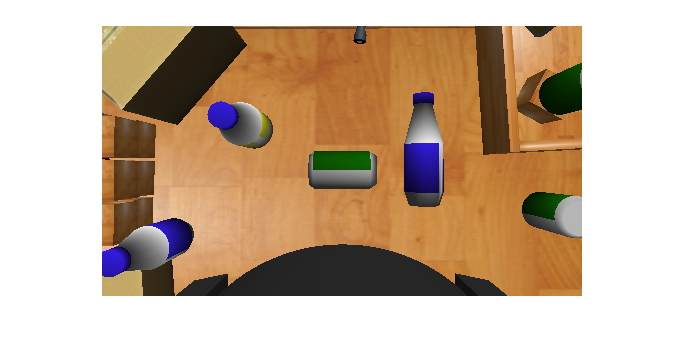

rgb=get_image('r');
imshow(rgb)

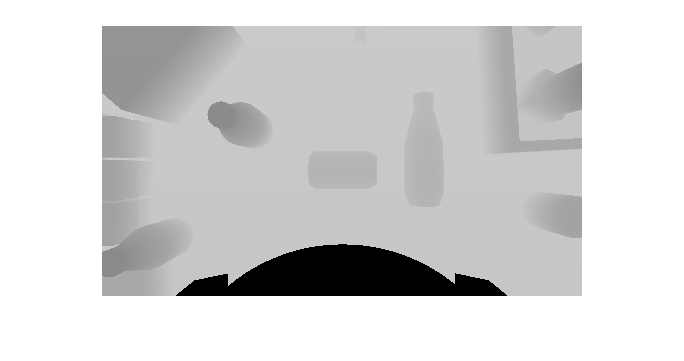

di=get_image('d');
imshow(di)

[prediction, bboxes, scores, labels] = classify(net,rgb);
bboxes

bboxes =   103.1111   77.0000   72.8889   45.0000
  305.7778   74.0000   42.6667  107.0000
  208.0000  124.0000   83.5556   55.0000
  419.5556  167.0000   56.8889   42.0000
    1.7778  186.0000   97.7778   72.0000


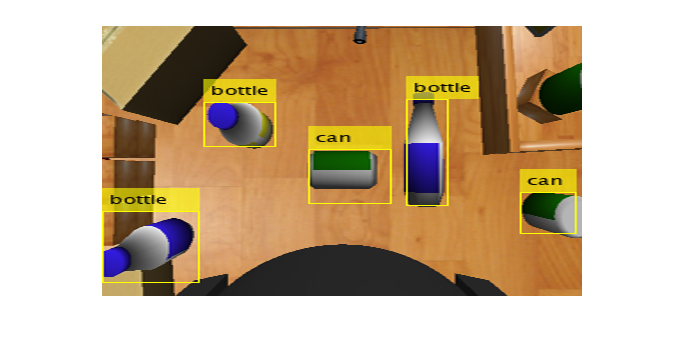

imshow(prediction)